TrendTradingHybridGAPatternSearch

Multivariable

clear 

tic

PatternSearchOpts = optimoptions (@patternsearch,'PlotFcn',{'optimplotfval','ptimplotx'}) ;
options = optimoptions ('ga', 'UseParallel', true, 'UseVectorized', ...
    false, "FunctionTolerance", 0.1, "MaxGenerations",50, 'FitnessLimit', -2.5)

options =   ga options:

   Set properties:
                    FitnessLimit: 2.5000
               FunctionTolerance: 0.1000
                  MaxGenerations: 50
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.8000
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50
                    MaxStallTime: Inf
                         MaxTime: Inf
                     MutationFcn: {@mutationg

options = optimoptions(options,'PlotFcn',{@gaplotbestf,@gaplotstopping}, ...
    'HybridFcn',{@patternsearch, PatternSearchOpts})

options =   ga options:

   Set properties:
                    FitnessLimit: 2.5000
               FunctionTolerance: 0.1000
                       HybridFcn: {@patternsearch  [1×1 optim.options.PatternsearchOptions]}
                  MaxGenerations: 50
                         PlotFcn: {@gaplotbestf  @gaplotstopping}
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.8000
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
               FitnessScalingFcn: @fitscalingrank
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50


ans =

     0


ans =

     0


EndCumSum =

     1


ans =

   -0.2328


ans =

     0


ans =

   -0.0080


ans =

    0.2671


EndCumSum =

    1.1550


TradingPeriod =

    9.0055


ans =

     0


EndCumSum =

     1


ans =

    0.0417


EndCumSum =

    0.7915


TradingPeriod =

    9.0055


CAGR =

     0


SharpeRatio =

   NaN


Sortino =

   NaN


MomMainRetThreshold =

    89

Elapsed time is 6.119525 seconds.

ans =

   -0.0139


ans =

    0.0393


EndCumSum =

    1.0762


TradingPeriod =

    9.0055


CAGR =

    0.0082


SharpeRatio =

   -0.1331


Sortino =

   -0.1976


MomMainRetThreshold =

    37

Elapsed time is 3.016491 seconds.

CAGR =

    0.0161


SharpeRatio =

   -0.1891


Sortino =

   -0.3127


MomMainRetThreshold =

   -11

Elapsed time is 7.122028 seconds.

ans =

     0


TradingPeriod =

    9.0055


CAGR =

     0


SharpeRatio =

   NaN


Sortino =

   NaN


MomMainRetThreshold =

    74

Elapsed time is 7.249914 seconds.

ans =

     0


TradingPe


ans =

   -0.0037


ans =

   -0.0058


ans =

     0


ans =

   -0.0080


ans =

    0.0051


EndCumSum =

    1.1290


TradingPeriod =

    9.0055


CAGR =

    0.0136


SharpeRatio =

   -1.3210


Sortino =

   -2.5857


MomMainRetThreshold =

    14

Elapsed time is 2.893876 seconds.

ans =

   -0.0038


ans =

    0.0165


EndCumSum =

    1.1466


TradingPeriod =

    9.0055


CAGR =

    0.0153


SharpeRatio =

   -0.7719


Sortino =

   -1.3925


MomMainRetThreshold =

    19

Elapsed time is 2.889044 seconds.

ans =

   -0.0081


ans =

     0


EndCumSum =

     1


TradingPeriod =

    9.0055


CAGR =

     0


SharpeRatio =

   NaN


Sortino =

   NaN


MomMainRetThreshold =

    33

Elapsed time is 2.921196 seconds.

ans =

   -0.0062


ans =

    0.0228


EndCumSum =

    1.0774


TradingPeriod =

    9.0055


CAGR =

    0.0083


SharpeRatio =

   -0.4092


Sortino =

   -0.7622


MomMainRetThreshold =

    12

Elapsed time is 2.852331 seconds.

ans =

   -0.0048


ans

ans = -0.0320

ans = 0.0350

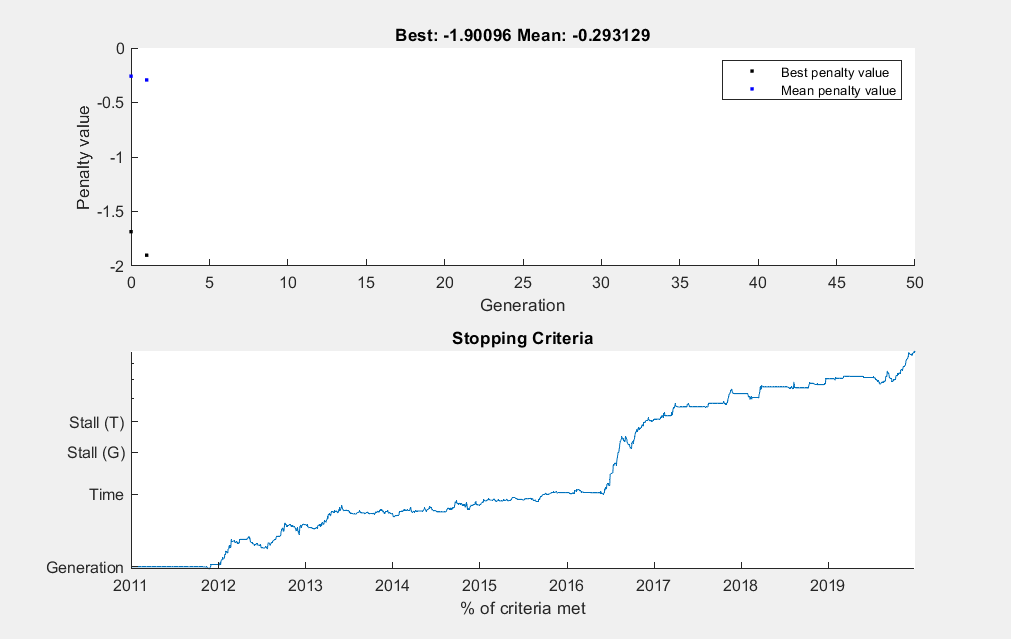

EndCumSum = 7.8893

TradingPeriod = 9.0055

CAGR = 0.2578

SharpeRatio = -1.9010

Sortino = -3.4471

MomMainRetThreshold = 61

Elapsed time is 3.676008 seconds.
Optimization terminated: minimum penalty fitness limit reached
and constraint violation is less than options.ConstraintTolerance.


x = 	1.0e+09 *

    1.1896    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


fval = -1.9010


% options.MaxGenerations = 50 ;
% options.FunctionTolerance = 1.0e-2 ;

FitnessFunction = @(x) TrendTradingFcnMultiVar(x) ;
nvars = 12 ;
IntCon = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12 ] ;
lb = [100, 1, -30, 1, 0, 0, 1, -20, 1, 1, -30, 1 ] ;
ub = [10^10, 90, 90, 90, 20, 20, 90, 90, 90, 90, 50, 90 ] ;

[x, fval] = ga(FitnessFunction, nvars, [], [], [], [], lb, ub, [], IntCon, options)



toc

Elapsed time is 4.270407 seconds.


writematrix (x, 'Trend Trading Input Output Data.xlsx', ...
    'sheet', "Optimized parameters V2")

